%% ============================================================
%  Loop over different t0 files and compare uhat, vhat, what
% ============================================================
syms y t t2 n;
% Assume your variable is:
% local_results = { [1x180 struct] };
t0= 20;
N = 32;
a = 1.2; 
b = 0;
% k0= 0.1;

[x, D, D2, D4,w] =finitediff(N,2);
h=eye(size(D));
h1=eye(size(D));
k2=(a.^2+b.^2)*h;
k=(a.^2+b.^2).^0.5*h1;
w1=w.^0.5;
W=diag(w1);
d=D+k;
WW=W*d;
V=[WW,zeros(N-2,N-2);zeros(N-2,N-2),W]; %126*126
c=D2-k2;


%U
Cn=0;
NN=100;
k0 = 0.1;
Re= 500;
g=1-exp(-k0.*t); %Acc
g=exp(-k0.*t); %Dec
an = (pi*n).^2./Re;  %lately
m=diff(g,t);
a1=subs(m,t,0);
m2=diff(m,t);
a2=subs(m2,t,t2);
e=exp(an.*t2);
a3=simplify(e*a2);
a4=simplify(int(a3, t2, 0, t),'Steps',200);
a5=a4+a1;
aa=-2.*Re.*(-1).^n./(pi.*n).^3.*(a5)+Cn;
a6=simplify(aa.*exp(-an.*t).*sin(n.*y.*pi),'Steps',100);
b1=Re./6.*m.*(y.^3-y);
b2=g.*y;
bb=b1+b2;
a7 = 0;
for ii = 1:NN
    a7 = a7 + subs(a6, n, ii);
end
U=a7+bb;

mm=diff(U);
mm2=diff(mm);
% U_yi = (subs(U, y, yi(2:N)));
% m_yi = (subs(mm, y, yi(2:N)));
% m2_yi = (subs(mm2, y, yi(2:N)));

% U_yi = (subs(U, y, x));
% m_yi = (subs(mm, y, x));
% m2_yi = (subs(mm2, y, x));
% U_yi_function = matlabFunction(U_yi);
% m_yi_function = matlabFunction(m_yi);

t0_list = [0, 20, 40, 60, 80, 100];
num_t0  = numel(t0_list);

dt = 1;
T  = 200;

% Choose which time index inside each t0 run to visualize:
% 'initial' : use first P(t) in each file
% 'peak'    : use the time where max eigenvalue of P(t) is largest
mode_time_choice = 'initial';

scaleFactor = 1;

% Physical wall-normal grid
y_grid = linspace(-1, 1, N).';

% Storage for mode profiles
u_modes = nan(N, num_t0);
v_modes = nan(N, num_t0);
w_modes = nan(N, num_t0);

j_pick_all = nan(1, num_t0);
t_pick_all = nan(1, num_t0);

% If your files do not store kx/kz, use these default values.
% IMPORTANT: make these consistent with the file data.
kx_default = a;
kz_default = b;

for jt = 1:num_t0

    t0_current = t0_list(jt);

    % ------------------------------------------------------------
    % Load file
    % ------------------------------------------------------------
%     baseName = sprintf('H_inf_norm_N_32_dt_1_t0_%d', t0_current);
%     baseName = sprintf('LMI_time_vayring_t_%d_kx_1_2_kz_0_acc_N_32', t0_current); 
%     baseName = sprintf('LMI_time_vayring_t_%d_kx_0_kz_1_6_dec_N_32', t0_current); 
    baseName = sprintf('LMI_time_vayring_t_%d_kx_0_kz_1_6_acc_N_32', t0_current); 

    
    if exist([baseName, '.mat'], 'file')
        fname = [baseName, '.mat'];
    elseif exist(baseName, 'file')
        fname = baseName;
    else
        error('Cannot find file for t0 = %d: %s or %s.mat', ...
              t0_current, baseName, baseName);
    end

    fprintf('Loading %s\n', fname);
    S = load(fname);

    if ~isfield(S, 'local_results')
        error('File %s does not contain local_results.', fname);
    end

    local_results = S.local_results;

    % Your file structure is usually local_results = { [1 x Nt struct] }
    if iscell(local_results)
        data = local_results{1};
    else
        data = local_results;
    end

    if iscell(data)
        data = data{1};
    end

    if ~isfield(data, 'P')
        error('The loaded data for t0 = %d does not contain P.', t0_current);
    end

    % ------------------------------------------------------------
    % Get kx, kz
    % ------------------------------------------------------------
    if isfield(data, 'kx')
        kx = data(1).kx;
    else
        kx = kx_default;
    end

    if isfield(data, 'kz')
        kz = data(1).kz;
    else
        kz = kz_default;
    end

    k2 = kx^2 + kz^2;

    if k2 == 0
        error('kx = 0 and kz = 0 gives k2 = 0. Cannot reconstruct velocity.');
    end

    % ------------------------------------------------------------
    % Compute eigenvectors of P(t)
    % ------------------------------------------------------------
    nsteps = numel(data);

    maxEig = nan(1, nsteps);
    maxIdx = nan(1, nsteps);
    eigVecStore = cell(1, nsteps);

    for jj = 1:nsteps

        P = data(jj).P;

        % Enforce Hermitian numerically
        P = 0.5 * (P + P');

        [V_eig, D_eig] = eig(P);

        eigReal = real(diag(D_eig));

        [maxEig(jj), maxIdx(jj)] = max(eigReal);

        eigVecStore{jj} = V_eig;
    end

    % ------------------------------------------------------------
    % Pick which time index to plot
    % ------------------------------------------------------------
    if strcmp(mode_time_choice, 'peak')
        [~, j_pick] = max(maxEig);
    else
        j_pick = 1;
    end

    j_pick_all(jt) = j_pick;

    if isfield(data, 't')
        t_pick_all(jt) = data(j_pick).t;
    else
        t_pick_all(jt) = t0_current + (j_pick - 1) * dt;
    end

    fprintf('t0 = %d: using j = %d, physical time = %.4f\n', ...
            t0_current, j_pick, t_pick_all(jt));

    % ------------------------------------------------------------
    % Extract dominant eigenvector of P
    % ------------------------------------------------------------
    q = eigVecStore{j_pick}(:, maxIdx(j_pick));

    % Transform back from weighted coordinates
    q = V \ q;

    % Split state vector
    v_interior   = q(1:(N-2));
    eta_interior = q((N-2)+1:end);

    % Pad with boundary zeros
    v_full   = [0; v_interior; 0];
    eta_full = [0; eta_interior; 0];

    % Compute dv/dy at interior points
    Dv_interior = D * v_interior;
    Dv_full     = [0; Dv_interior; 0];

    % ------------------------------------------------------------
    % Reconstruct velocity components
    % ------------------------------------------------------------
    u_hat = (1/k2) * (1i*kx * Dv_full - 1i*kz * eta_full);
    v_hat = v_full;
    w_hat = (1/k2) * (1i*kz * Dv_full + 1i*kx * eta_full);

    % ------------------------------------------------------------
    % Normalize mode amplitude
    % This is important because eigenvectors have arbitrary scaling.
    % ------------------------------------------------------------
%     mode_norm = sqrt(trapz(y_grid, ...
%         abs(u_hat).^2 + abs(v_hat).^2 + abs(w_hat).^2));
% 
%     if mode_norm > 0
%         u_hat = u_hat / mode_norm;
%         v_hat = v_hat / mode_norm;
%         w_hat = w_hat / mode_norm;
%     end

    % ------------------------------------------------------------
    % Phase alignment
    % This is important because complex eigenvectors have arbitrary phase.
    % ------------------------------------------------------------
%     stacked_mode = [u_hat; v_hat; w_hat];
%     [~, ref_idx] = max(abs(stacked_mode));
%     phase_ref = angle(stacked_mode(ref_idx));
% 
%     u_hat = u_hat * exp(-1i * phase_ref);
%     v_hat = v_hat * exp(-1i * phase_ref);
%     w_hat = w_hat * exp(-1i * phase_ref);

    % Store
    u_modes(:, jt) = scaleFactor * u_hat(:);
    v_modes(:, jt) = scaleFactor * v_hat(:);
    w_modes(:, jt) = scaleFactor * w_hat(:);

end

Loading LMI_time_vayring_t_0_kx_0_kz_1_6_acc_N_32.mat


t0 = 0: using j = 1, physical time = 0.0000


Loading LMI_time_vayring_t_20_kx_0_kz_1_6_acc_N_32.mat


t0 = 20: using j = 1, physical time = 20.0000


Loading LMI_time_vayring_t_40_kx_0_kz_1_6_acc_N_32.mat


t0 = 40: using j = 1, physical time = 40.0000


Loading LMI_time_vayring_t_60_kx_0_kz_1_6_acc_N_32.mat


t0 = 60: using j = 1, physical time = 60.0000


Loading LMI_time_vayring_t_80_kx_0_kz_1_6_acc_N_32.mat


t0 = 80: using j = 1, physical time = 80.0000


Loading LMI_time_vayring_t_100_kx_0_kz_1_6_acc_N_32.mat


t0 = 100: using j = 1, physical time = 100.0000


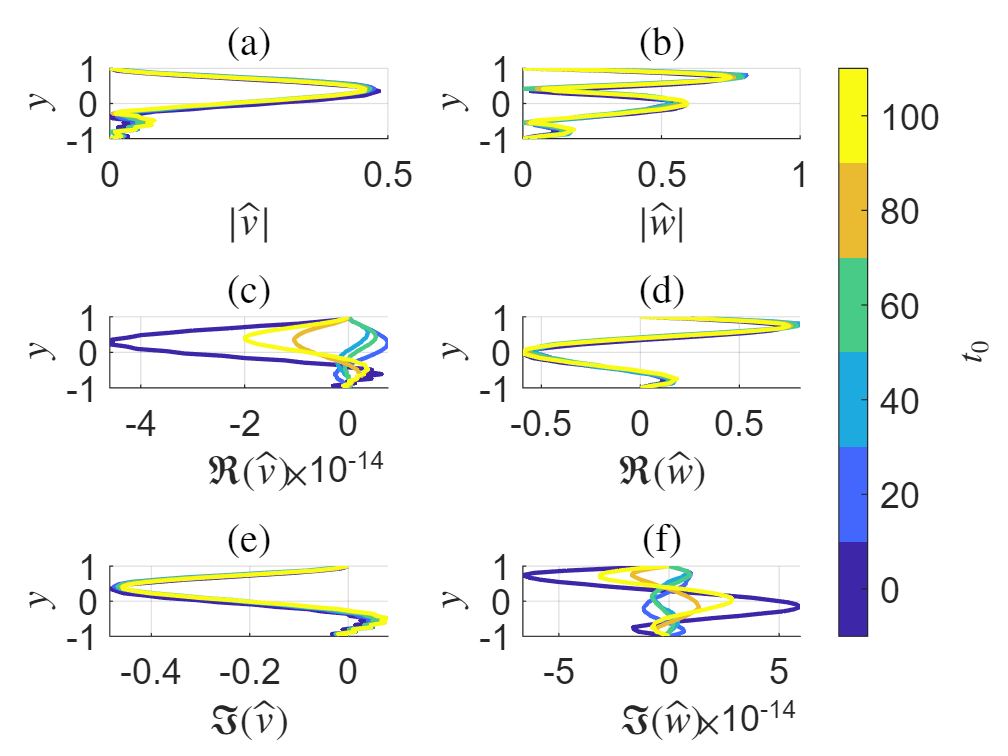



%% ============================================================
%  3 x 2 panel structure:
%
%   (a) (b)   -> magnitude
%   (c) (d)   -> real part
%   (e) (f)   -> imaginary part
%
%  For kz = 0: columns are u, v
%  For kx = 0: columns are v, w
% ============================================================

tol_k = 1e-12;

if abs(kz) < tol_k && abs(kx) > tol_k
    % kz = 0 case: use u and v
    comp_titles = {'$\hat{u}$', '$\hat{v}$'};
    comp_names  = {'u','v'};
    comp_data   = {u_modes, v_modes};

elseif abs(kx) < tol_k && abs(kz) > tol_k
    % kx = 0 case: use v and w
    comp_titles = {'$\hat{v}$', '$\hat{w}$'};
    comp_names  = {'v','w'};
    comp_data   = {v_modes, w_modes};

else
    error('This 3x2 layout is for the two-component case only. For the general case, use a 3x3 layout.');
end

cmap = parula(num_t0);

label_fs  = 18;
title_fs  = 18;
axis_fs   = 15;

figure('Color','w','Name','Mode profiles over different t_0');
tiledlayout(3,2,'Padding','compact','TileSpacing','compact');

ax = gobjects(6,1);

%% ---------------- Row 1: magnitude ----------------
% (a)
ax(1) = nexttile;
hold on;
for jt = 1:num_t0
    plot(abs(comp_data{1}(:,jt)), y_grid, ...
        'Color', cmap(jt,:), 'LineWidth', 1.8);
end
grid on;
xlabel(['$|\hat{' comp_names{1} '}|$'], 'Interpreter','latex', 'FontSize', label_fs);
ylabel('$y$', 'Interpreter','latex', 'FontSize', label_fs);
title(['(a)'], 'Interpreter','latex', 'FontSize', title_fs);
ylim([min(y_grid), max(y_grid)]);
set(gca, 'FontSize', axis_fs);

% (b)
ax(2) = nexttile;
hold on;
for jt = 1:num_t0
    plot(abs(comp_data{2}(:,jt)), y_grid, ...
        'Color', cmap(jt,:), 'LineWidth', 1.8);
end
grid on;
xlabel(['$|\hat{' comp_names{2} '}|$'], 'Interpreter','latex', 'FontSize', label_fs);
ylabel('$y$', 'Interpreter','latex', 'FontSize', label_fs);
title(['(b)'], 'Interpreter','latex', 'FontSize', title_fs);
ylim([min(y_grid), max(y_grid)]);
set(gca, 'FontSize', axis_fs);

%% ---------------- Row 2: real part ----------------
% (c)
ax(3) = nexttile;
hold on;
for jt = 1:num_t0
    plot(real(comp_data{1}(:,jt)), y_grid, ...
        'Color', cmap(jt,:), 'LineWidth', 1.8);
end
grid on;
xlabel(['$\Re(\hat{' comp_names{1} '})$'], 'Interpreter','latex', 'FontSize', label_fs);
ylabel('$y$', 'Interpreter','latex', 'FontSize', label_fs);
title(['(c)'], 'Interpreter','latex', 'FontSize', title_fs);
ylim([min(y_grid), max(y_grid)]);
set(gca, 'FontSize', axis_fs);

% (d)
ax(4) = nexttile;
hold on;
for jt = 1:num_t0
    plot(real(comp_data{2}(:,jt)), y_grid, ...
        'Color', cmap(jt,:), 'LineWidth', 1.8);
end
grid on;
xlabel(['$\Re(\hat{' comp_names{2} '})$'], 'Interpreter','latex', 'FontSize', label_fs);
ylabel('$y$', 'Interpreter','latex', 'FontSize', label_fs);
title(['(d)'], 'Interpreter','latex', 'FontSize', title_fs);
ylim([min(y_grid), max(y_grid)]);
set(gca, 'FontSize', axis_fs);

%% ---------------- Row 3: imaginary part ----------------
% (e)
ax(5) = nexttile;
hold on;
for jt = 1:num_t0
    plot(imag(comp_data{1}(:,jt)), y_grid, ...
        'Color', cmap(jt,:), 'LineWidth', 1.8);
end
grid on;
xlabel(['$\Im(\hat{' comp_names{1} '})$'], 'Interpreter','latex', 'FontSize', label_fs);
ylabel('$y$', 'Interpreter','latex', 'FontSize', label_fs);
title(['(e)'], 'Interpreter','latex', 'FontSize', title_fs);
ylim([min(y_grid), max(y_grid)]);
set(gca, 'FontSize', axis_fs);

% (f)
ax(6) = nexttile;
hold on;
for jt = 1:num_t0
    plot(imag(comp_data{2}(:,jt)), y_grid, ...
        'Color', cmap(jt,:), 'LineWidth', 1.8);
end
grid on;
xlabel(['$\Im(\hat{' comp_names{2} '})$'], 'Interpreter','latex', 'FontSize', label_fs);
ylabel('$y$', 'Interpreter','latex', 'FontSize', label_fs);
title('(f)', 'Interpreter','latex', 'FontSize', title_fs);
ylim([min(y_grid), max(y_grid)]);
set(gca, 'FontSize', axis_fs);

%% ---------------- Shared colorbar ----------------
colormap(cmap);

for i = 1:6
    caxis(ax(i), [0.5, num_t0 + 0.5]);
end

c = colorbar(ax(6));
c.Layout.Tile = 'east';
c.Ticks = 1:num_t0;
c.TickLabels = arrayfun(@(x) num2str(x), t0_list, 'UniformOutput', false);
c.Label.String = '$t_0$';
c.Label.Interpreter = 'latex';
c.Label.FontSize = label_fs;
c.FontSize = axis_fs;

function [x, D1, D2, D4,w] =finitediff(N,L)

%Differentiation matrix using finite difference scheme.
%This is suitable for Dirichlet boundary condition v(x=L/2)=v(x=-L/2)=0 at
%the boundary and Neumann boundary condition v'(x=L/2)=v'(x=-L/2)=0. 

dx=L/N;%get grid spacing. 

x=linspace(-L/2,L/2,N);%get the grid point location

x=x(2:end-1); %delete the first and last points that are zero. 

w=dx*ones(1,N-2);%integration weighting 

N_diff=N-2;%The size of differentiation matrices

%First order derivative based on central difference
%f'(x_i)=(f(x_{i+1})-f(x_{i-1})/(2*dx)
%We also use the boundary condition that x_0=x_N=0
D1_stencil=diag(-1*ones(1,N_diff-1),1)+diag(ones(1,N_diff-1),-1);
D1=D1_stencil/(2*dx);

%Second order derivative based on central difference
%f''(x_i)=(f(x_{i+1})-2f(x_i)+f(x_{i-1})/(dx^2)
%We also use the boundary condition that x_0=x_N=0
D2_stencil=(diag(-2*ones(1,N_diff))+diag(ones(1,N_diff-1),1)+diag(ones(1,N_diff-1),-1));
D2=D2_stencil/dx^2;

%Forth order derivative based on central difference
%f''''(x_i)=(f(x_{i+2})-4f(x_{i+1})+6f(x_i)-4f(x_{i-1})+f(x_{i-2})/(dx^4)
%This differentiation matrix only go through x_1 up to x_{N-1}
D4_stencil=(diag(6*ones(1,N_diff))+diag(-4*ones(1,N_diff-1),1)+diag(-4*ones(1,N_diff-1),-1)...
    + diag(ones(1,N_diff-2),2)+diag(ones(1,N_diff-2),-2));

%Here, we use the Neumann boundary condition that x_0'=x_N'=0
%such that x_1=x_{-1} and x_{N-1}=x_{N+1} for the ghost points. Then we
%also use the condition x_0 and x_N=0 to express all values based on x_1 up
%to x_{N-1}
D4_stencil(1,1)=D4_stencil(1,1)+1;
D4_stencil(end,end)=D4_stencil(end,end)+1;

D4=D4_stencil/dx^4;

end
